**6.6 ****Linear Prediction on the Stock Market **

Linear prediction is one of the most widely-used approaches to time series analysis involving applications such as speech coding, seismology, and frequency response modeling. In this exercise, you will learn how linear prediction can be used to design a discrete-time finite- length impulse response (**FIR**) filter to solve both a time-domain prediction problem and a frequency-domain modeling problem. 

In the prediction problem, you observe a signal $x[n] $ and wish to design a system that can predict future values of the signal based solely upon past values. For linear prediction, this system is an **FIR** filter which computes a prediction based upon a linear combination of past values, 

eq 6.27

                            
$$\hat{x}[n] = -\sum_{k=1}^{p}a_kx[n-k],$$
                        

where $\hat{x}[n]$ is the predicted value of $x[n]$. Since p previous values of the signal are used to formulate the prediction, this is a pth-order predictor. Given a fixed filter order, p, the linear prediction problem is to determine a set of filter coefficients, $a_k$, that best perform the prediction in Eq. (6.27). The most common measure of determining the "best" coefficients,  $a_k$, is to select those coefficients that minimize the total squared prediction error 

eq6.28

                        
$$E=\sum_{n=1}^{N} |e[n]|^2= \sum_{n=1}^{N} |x[n]-\hat{x}[n]  |^2,$$


assuming the sequence $x[n]$ has length **N**. Several approaches can be used to solve for the $a_k$'s  that minimize **E** in Eq. (6.28).  Perhaps the simplest is to use that MATLAB \ operator for solving simultaneous linear equations. Assuming $ N > P$ , the linear prediction problem can be posed in matrix form as 

Eq6.29

            
$$-\left[\matrix{ x[1]  &...   & x[p] \cr

x[2]  &...   & x[p+1] \cr
\vdots  & ...   & \vdots \cr
x[N-p]  &...   & x[N-1] \cr


} \right]


\left[\matrix{ a_1 \cr

\vdots \cr
a_p \cr


} \right]

+



\left[\matrix{ e[p+1] \cr
e[p+2] \cr
\vdots \cr
e[N] \cr


} \right]


=



\left[\matrix{ x[p+1] \cr
x[p+2] \cr
\vdots \cr
x[N] \cr


} \right]








$$
			

or compactly as `-Xa+e=x. `This equation can be used to solve for the vector **a **which minimizes the total squared prediction error, `e'*e. `The convention of incorporating the minus sign on the left hand side of Eq. (6.29) is so that the "prediction-error filter" can be expressed as `e=Xa+x `

			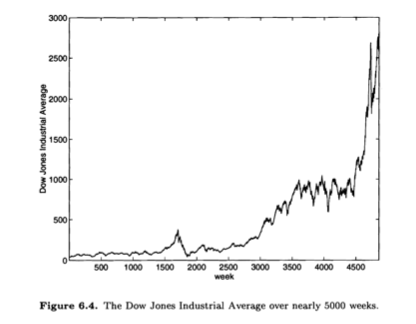

The problems in this exercise will apply linear prediction to the financial data stored in the file **djia.mat,** which is in the Computer Explorations Toolbox. If this file has been loaded correctly, then typing who should result in 				

**>> who**

**Your variables are: dj**

**djia **			

where **djia** is the Dow Jones Industrial Average (DJIA) index sampled weekly for approximately 94 years. The **DJIA** for these weeks is plotted in Figure 6.4. 

In this set of problems, you will attempt to make a fortune by investing with the following strategy: 

(i)  construct a linear predictor based on past DJIA data; 											

(ii)  use your predictor to guess the value of next week's DJIA based on the past p weeks; 										

(iii)  if the DJIA increases by more than the risk-free interest rate earned by a savings account, you invest all of your money in the DJIA; 						

(iv)  if the DJIA increases by less, you put all of your money in the bank. 						

You will assume that if you decide put all of your money in the **DJIA** for the week, then you will earn exactly the gain that was earned in the **DJIA**. For example, if you had $1000 in the **DJIA** at week $n$ and the DJIA at week $n+1$ was given by **djia(n+l)** , then at the end of week  $n+1$, you have **$1000*djia(n+l)/dj ia(n)**. Also assume that the savings account always earns ***r ***= **3% **annual interest, compounded weekly, i.e., your **$1000** would be worth** $1000*(1+0.03/52)** after one week in the bank. 

**Basic Problems **

(a).  Plot the **DJIA** data on both a linear and a semi-logarithmic scale. Assuming that you started with **$1000** and invested all of your money in the **DJIA**, how much money would you have at the end of the investment interval (4861 weeks)? If you had put all of your money in the bank at 3% annual percentage rate (APR),compounded weekly, what rate would you need to achieve the same level of performance? If $ r = 0.03$ is the APR, then the bank balance after N weeks from a weekly compounded interest bearing account is equal to $g=(1+r/52)^N$ the initial balance. 						

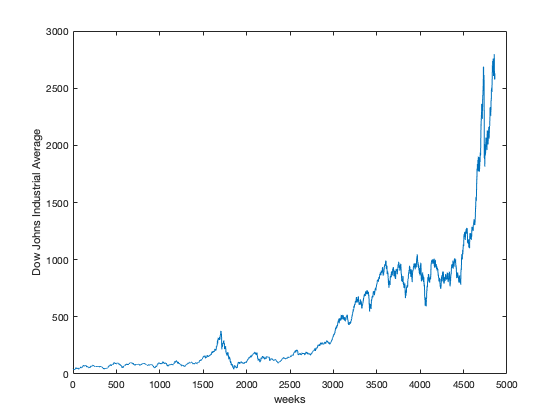

clf;
clc;
load djia.mat

figure(1);
plot(djia);xlabel('weeks');ylabel('Dow Johns Industrial Average');

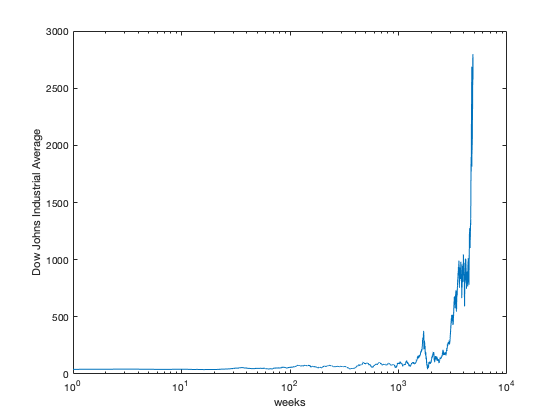

clf ;figure(2); semilogx(djia);xlabel('weeks');ylabel('Dow Johns Industrial Average');

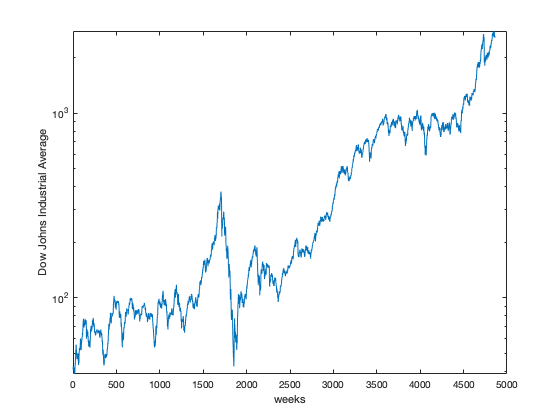

clf;figure(3); semilogy(djia); xlabel('weeks');ylabel('Dow Johns Industrial Average');

clf;
money=1000;
N=length(djia);
week=1:N;

djiasaving=zeros(1,N);
djiasaving(1)=money;
for i=2:N
    djiasaving(i)=djiasaving(i-1)*djia(i)/djia(i-1);
end
r=3;

banksaving=zeros(1,N);
banksaving(1)=money;
for i=2:N
    
    banksaving(i)=money*(1+r/(100*52))^(i-1);
end


fprintf('p after investing in djia %f\n', djiasaving(N-1))

p after investing in djia 63199.412053


fprintf('p after investing in saving account  %f', banksaving(N-1))

p after investing in saving account  16485.165342

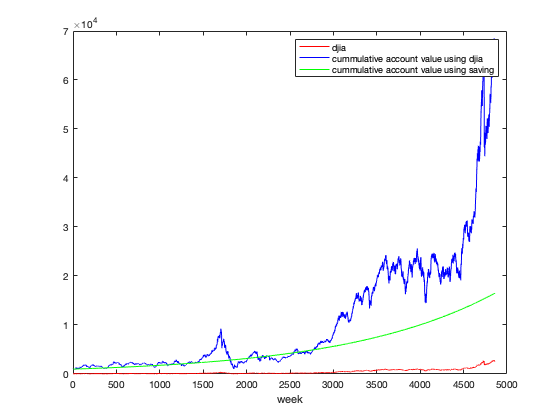

clf;
figure(4);

plot(week,djia,'r',week,djiasaving,'b',week,banksaving,'g');
legend('djia','cummulative account value using djia','cummulative account value using saving');
xlabel('week');

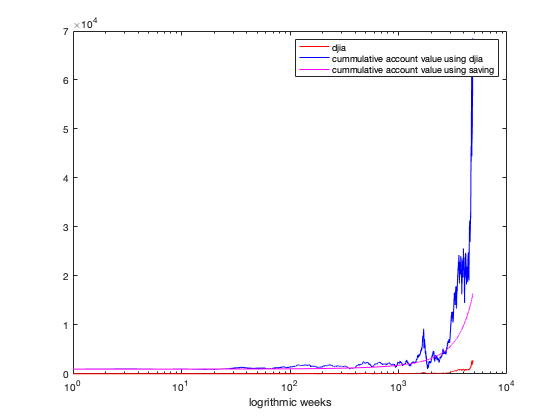

clf;
figure(5);
semilogx(week,djia,'r',week,djiasaving,'b',week,banksaving,'m');
legend('djia','cummulative account value using djia','cummulative account value using saving');
xlabel('logrithmic weeks');

(b).  Assume that p = 3 and create the vector **x** and matrix **X** in Eq. (6.29) from the first decade of data, i.e., use N = 520 weeks. The MATLAB \ operator can be used to solve for the vector a that minimizes the inner product $e'*e$ in Eq. (6.29). Solve for the linear predictor coefficients using the MATLAB** \** operator by **a=-X\x.** 						

clc;

N=520;
week=1:N;
p=3;

X=zeros(N-p,p);
for i=1:N-p
    X(i,:)=djia(i:i+p-1)';
end

x=djia(p+1:N);

a=-X\x

a =    -0.1156
    0.4667
   -1.3521


(c).  Create the vector of predicted values for the first decade of data using **xhat1=-X*a**. Also create the vector **xhat2** by appropriately using **filter** on the sequence **djia** . Note that the coefficients in the vector **a** are in the reverse of the order required by **filter**. Plot the predicted values on the same set of axes as the actual weekly average. Also determine the total squared error between the predicted and actual values. As a check, do this two ways. First use **e=x+X*a **to compute the prediction error, and then calculate the error by subtracting your predicted sequence **xhat2** from the actual values and make sure that these are the same. 						

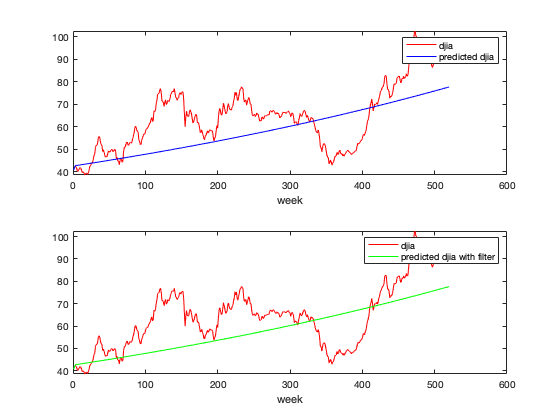

clc;
clf;

% preallocate xhat1
xhat1=zeros(N,1);
xhat1(1:p)=djia(1:p);

for i=p+1:N
    X1=xhat1(i-p:i-1)';
    xhat1(i)=-X1*a;
end

% because here are starting from a1 a2 to aN
% but we need them in reverse order i.e. from page 121 eq 6.27
% we need A1 for x(n) A2 for x(n-1) A3 for x(n-3) etc.
% 
% building new a, na by inverting the previous a
%
%

an=zeros(p,1);
for i=1:p
    an(p+1-i)=a(i);
end

%
% defining b to be this new an but from the 6.27 page 121 since we have -ve
% used here hence same we will do
%

b=-an;

xhat2=zeros(N,1);
xhat2(1:p)=djia(1:p);

for i=p+1:N
    X1=xhat2(i-p:i-1)';
    Y1=filter(b,1,X1);
    xhat2(i)=Y1(length(Y1));
    xhat2(i);
end

figure(6);

subplot(211);
plot(week,djia(1:N),'r',week,xhat1,'b');
legend('djia','predicted djia');
xlabel('week');

subplot(212);
plot(week,djia(1:N),'r',week,xhat2,'g');
legend('djia','predicted djia with filter');
xlabel('week');

(d). Calculate and plot the total squared prediction error as a function of **p** for **p=1,...10 **. You will have to find the predictor coefficients a1, ..., a10 for each model order p, and then calculate each of the prediction errors. What is an appropriate value for **p**, i.e., is there a value of **p** after which the decrease in prediction error is negligible? 

clc;
clf;


p=10;

X=zeros(N-p,p);
for i=1:N-p
    X(i,:)=djia(i:i+p-1)';
end

x=djia(p+1:N);

a=-X\x

a =     0.0359
   -0.0608
   -0.0035
    0.0429
   -0.0311
    0.0090
    0.0622
   -0.1877
    0.4908
   -1.3585


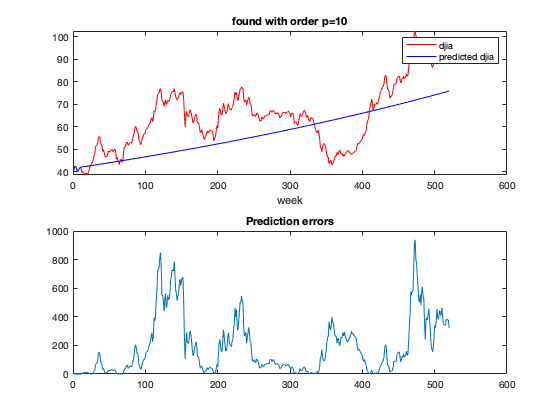


xhat1=zeros(N,1);
xhat1(1:p)=djia(1:p);

for i=p+1:N
    X1=xhat1(i-p:i-1)';
    xhat1(i)=-X1*a;
end

e1=xhat1-djia(1:N);
e1s=e1.*e1;

figure(7);

subplot(211);
plot(week,djia(1:N),'r',week,xhat1,'b');
legend('djia','predicted djia');
xlabel('week');
title('found with order p=10');

subplot(212);
plot(week,e1s);title('Prediction errors')

**Intermediate Problems **

(e). Given the predictor you designed based on the first decade of data and the model order you have selected from Part (d), you will now test the investment strategy outlined in the introduction. Give yourself $1000 at the end of the p th week, and make 520 trading decisions based on the output of your predictor. First, determine an upper bound on the amount of money you could make. This would be how much you could make if you were omniscient, i.e., if you knew which direction the stock market was going each week and were always invested in the better of either the bank or the DJIA. Now, as a lower bound, calculate how much money you would make if you left all of your money in the bank and earned a gain of (1+0.03152) each week. As another lower bound, determine how much you would make with the "buy-and-hold" strategy, where you put all your money in the DJIA every week. Finally, calculate how much money you would make with your predictor. What is the equivalent APR that the bank would have had to pay you to achieve the same gain as your predictor? 

[ub,lb] = bounds(xhat1) %lower bound and upper bound

ub = 40.2600

lb = 75.8443

[ub2,lb2] = bounds(xhat2) 

ub2 = 40.8200

lb2 = 77.6586

% New APR 
banksaving2=zeros(1,N);
banksaving2(1)=money;
for i=2:520
    banksaving2(i)=money*((1+0.03152)^(i));
end
a=banksaving2(520)*100;

apr_rate=lb/a;
apr_rate % APR is %7.67 

apr_rate = 7.4395e-11

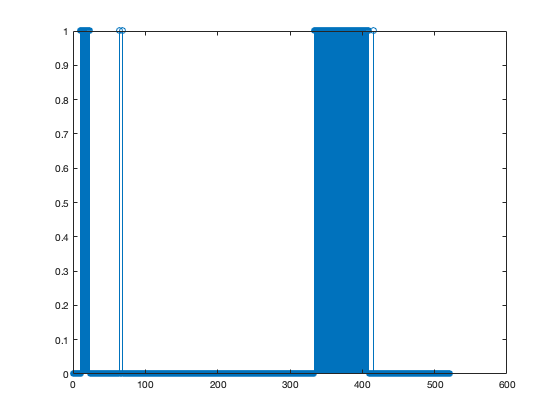

%
% Investment Strategy
%
clf;
decisionsaving=zeros(1,N);

for i=1:N 
    k=1;
    if djia(i) < xhat1(i)
        decisionsaving(i)=1;
    end
   
    
end
stem(decisionsaving);

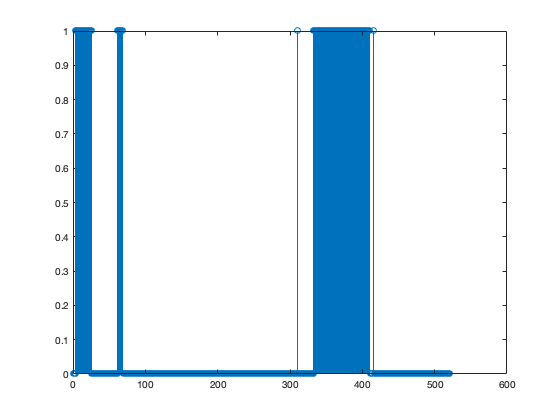

clf;
decisionsaving2=zeros(1,N);

for i=1:N 
    k=1;
    if djia(i) < xhat2(i)
        decisionsaving2(i)=1;
    end
   
    
end
stem(decisionsaving2);

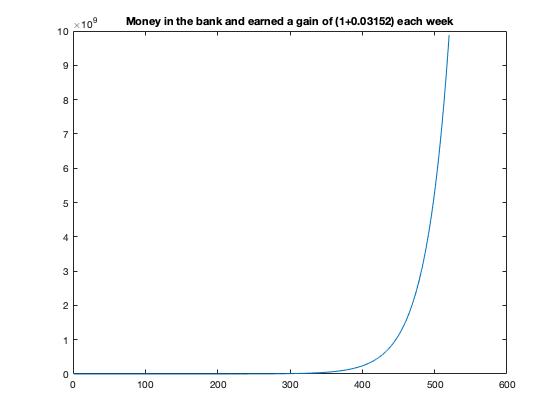

clf;
clc;
banksaving2=zeros(1,N);
banksaving2(1)=money;
for i=2:520
    banksaving2(i)=money*((1+0.03152)^(i-1));
    
end

plot(banksaving2);title('Money in the bank and earned a gain of (1+0.03152) each week');

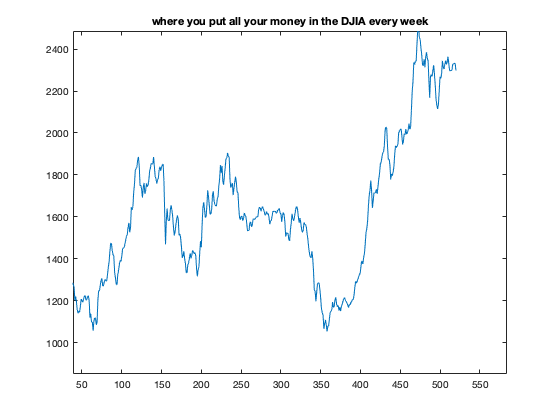

clf;
clc;
djiasaving2=zeros(1,N);

djiasaving2(1)=money;
for i=2:520
    djiasaving2(i)=djiasaving2(i-1)*djia(i)/djia(i-1);
    
end

plot(djiasaving2);title('where you put all your money in the DJIA every week');

(f). Now use your prediction strategy on the most recent decade in the data, i.e., the last 520 weeks of the DJIA. Calculate how you did and how each of the bounds perform: 			

best-possible,all in the bank account, and buy-and-hold. Also calculate the equivalent APR for your predictor. 